# Function Reference List

Copyright 2024 The MathWorks, Inc.

The functions listed below are used in the workflows described in this project. In this document, you will learn how to use these functions and specify their name-value-pairs.

## Create Building

#### 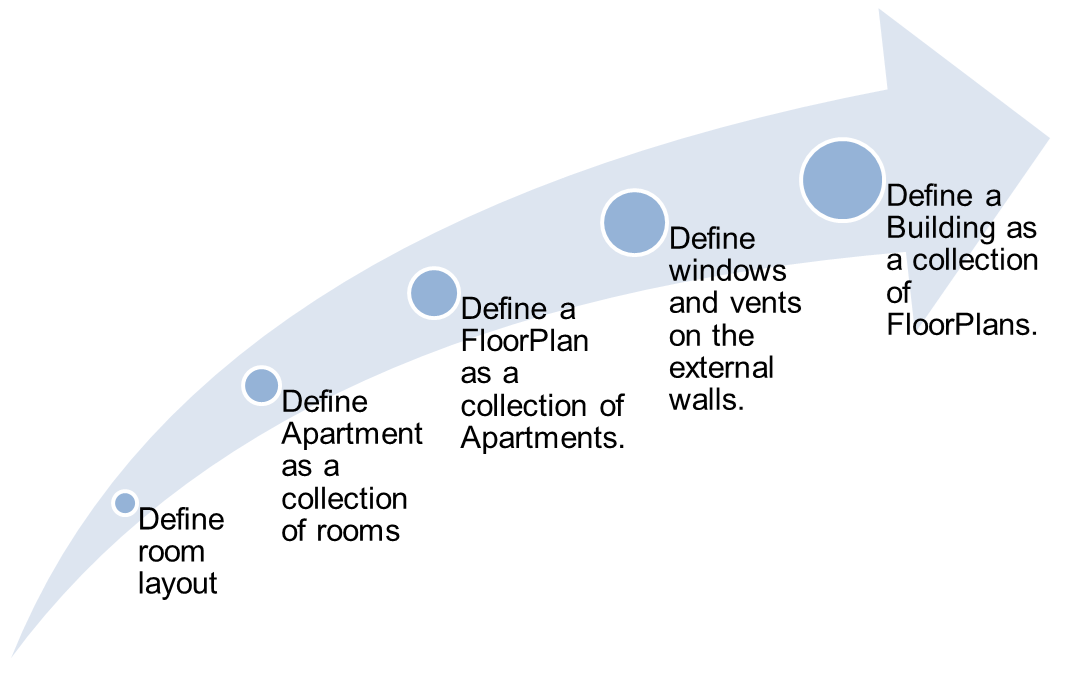

### addRoomToFloorPlan

This function adds room data to a floor plan. 

**Arguments:**

- `FloorPlan`: Data struct for apartment unit floorplan.

- `NewRoom`: Name of the new room being added to the `FloorPlan`, specified as a string.

- `Vertex`: The point on the x-y plane that defines the room vertex or one of the corners, specified as a vector of Simscape values. It represents the coordinate locations in the x and y direction, or the east-west and north-south direction for the room starting point.

- `Length`: Length of the new room, specified as a Simscape value.

- `Width`: Width of the new room, specified as a Simscape value.

- `Angle`: Angle by which the room is rotated, specified as a Simscape value.

- `Plot`: An optional argument, specified as either *true* or *false*. The default value is *false*. When you specify *true*, the function plots the room being added along with other rooms already present in the `FloorPlan` data struct definition. The plot can help to visually confirm the room placement with reference to other rooms.

**Example:**

### defineSingleApartmentUnit

This function defines one apartment unit. 

**Arguments:**

- Apartment: Data struct for apartment unit.

- `Tol`: Percentage value used to detect if two sides of a room are overlapping or not. This value is used in auto-detecting common walls and helps in creating building thermal network in Simscape.

**Example:**

### **copyMoveRotateForNewApartment**

This function can move, rotate, and create a copy of an existing apartment. Use this function to create copies of apartments that have similar layout.

**Arguments: **

- `Apartment`: Specify apartment data struct.

- `MoveDistance`: Specify distance vector for moving floorplan in XY plane.

- `RotationAngle`: Specify angle for rotation of floorplan.

- `RotateAboutRoom`: Name of the room around which the floorplan is to be rotate.

- `Tol`: Percentage value and used to detect if two sides of a room are overlapping or not. This value is used in auto-detecting common walls and helps in creating building thermal network in Simscape.

**Example:**

### **defineBuildingFloorPlan**

This function combines multiple apartment definitions into one single floorplan.

**Arguments:**

- `Apartments`: Cell array of data struct for all apartment units. This function combines one or more apartment units into one single floorplan. It is specified as a cell array of the different apartment data struct.

**Example:**

### visualizeBuildingWallsToAddWindowsVents

This function visualizes the external walls of a building and adds a number for specifying the wall section. See addOpeningOnWallSection.

**Arguments:**

- `FloorPlan`: Building floorplan.

**Example:**

### addOpeningOnWallSection

This function adds window and vent definition to an external wall in the building. The visualizeBuildingWallsToAddWindowsVents function represents the external wall edges and adds a number to them. These number are used to specify the wall portion to add a window or vent.

**Arguments:**

- FloorPlan: Building floorplan.

- Data: A matrix of 3 columns and number of rows equal to the number of openings you wish to specify. Column 1 and 2 refer to indices of the wall section represented on the floorplan from the function visualizeBuildingWallsToAddWindowsVents. The 3rd column is a scalar value between 0 and 1, which represents what fraction of total wall area that the opening occupies. For example, a value of 0.60 would represent an opening that covers 60% of the wall area.

- `Type`: A string to specify window or a vent.

**Example:**

### generateBuilding3Dlayout

This function constructs a 3D building from a floorplan data.

**Arguments:**

- BuildingName: Name of the building, specified as a string.

- `BuildingFloorPlan`: Building floor plan data struct.

- `NumberOfLevels`: Number of floors to be created in the building, specified as an integer.

- `LevelHeight`: Height of each floor, specified as a scalar value.

- `Tol`: Tolerance value for wall proximity detection.

**Example:**

### getParamsForSimscapeComponent

This function combines all parameters needed to parameterize the custom Building block and the Operational Data block in Simscape.

**Arguments:**

- `Building`: Data struct, with all the information related to building. This is the data struct obtained from the part XML.

- `PhysicsTableData`: This argument is optional. It is not required unless you are running a detailed analysis with heat pumps, radiators, and underfloor piping system. It is a table that contains all operational variables for the detailed analysis. These values may change with time or the choice of the room. See Initialize Room Operational Physics Data.

**Example:**

% For detailed analysis
params = getParamsForSimscapeComponent(Building=buildingDataStruct,...
                                       PhysicsTableData=physTable);

% For requriement analysis, detailed physics table data is not required
params = getParamsForSimscapeComponent(Building=buildingDataStruct);

### setParametersForBuildingCustomComponent

This function combines all parameters needed to parameterize the custom Building block and the Operational Data block in Simscape.

**Arguments:**

- `Building`: Name of the building, specified as a string.

- `BuildingNetworkData`: Output of getParamsForSimscapeComponent function. It contains matrices to specify thermal network model for the entire building.

- `PhysicsTableData`: Parameter struct related to physics table data and ambient modelling.

- `RoomModel`: A selection of room type; for more information, see [Room Modelling Options](matlab:open('./html/DocumentationRoomModellingOptions.html')).

The function returns the model name, present in `Components/Building`, to be used for analysis.

**Example:**

### editHVACModelParameterRoom

This function edits the HVAC radiator and underfloor pipe models in the building. You can specify varying coverage of pipes across the rooms, or different floors, with this function. 

**Arguments:**

- `Building`: building data struct.

- `ListOfLevels`: A column or a list of building levels for which value needs to be updated.

- `ListOfRooms`: A column of strings specifying room names to be edited.

- `ModelParameter`: Option to select between radiator and underfloor piping value edits.

- `NewValue`: value of the new parameter.

**Example:**

### initializeRoomOperationalPhysicsData

This function parameterizes the O`perationalData` block and specifies the variables that impact building simulation, `Heat Source (W)`, `Electrical Load (W)`, `Room Occupancy Level`, and `HVAC On/Off`. This function sets some default values to these variables, at all time stamps, and for all rooms at all levels of the building. 

- `Heat Source (W)` - Heat source defined in Watts.

- `Electrical Load (W)` - Electrical power consumption in Watts.

- `Room Occupancy Level` - Number of people occupying a room at a given instance of time, specified as integer.

- `HVAC On/Off` - Specified as True/False to denote if HVAC is needed in a room at a point in time or not. Default is True which means that the HVAC is On.

**Arguments:**

- `Building`: Building data struct.

- `Duration`: Datetime vector of timestamps of interest.

**Example**:

### editParametersForBuildingPhysics

This is a helper function to edit properties of the table created by initializeRoomOperationalPhysicsData function. 

**Arguments:**

- `PhysicsTable`: Tabular data for physics values.

- `ListOfLevels`: List of floors or levels in building with variables to edit.

- `ListOfRooms`: List of rooms for with variables to edit.

- `ListOfTimeValues`: List of datetime value for which vaiable value needs editing.

- `PhysicsParameter`: Variable of interest.

- `NewValue`: New value for the variable.

**Example**:

## Ambient Modelling

### getAmbientTemperatureVariationModelData

This function finds the sunrise and sunset times for the specified days and parameterizes the **Ambient** custom block.

**Arguments:**

- `DateTimeVector`: Datetime vector of timestamps of interest.

- `Location`: Location, longitude, and latitude data in table format

- `DayLightSavingHrs`: Day light saving hours.

**Example**:

## Solar Modelling

### getGeoLocationForMajorCities

This function defines the longitude and the latitude for well known cities in the world. This data is required to compute the solar radiation value. If your city is not available in the list, you can create an empty template and add data to it.

**Arguments:**

- `CityName`: A string, denoting the name of the city.

**Example**:

### getHourlyBuildingSolarLoad

This function calculates the solar load on a building between two specified date and time.

**Arguments:**

- `Building`: A string, denoting the name of the city.

- `Location`: A table with geographical location data. It is the output of the function getGeoLocationForMajorCities.

- `DayLightSavingHrs`: Daylight saving hours.

- `StartTime`: Datetime parameter for start of simulation.

- `EndTime`: Datetime parameter for end of simulation.

**Example**:

## Read/Write Building Data

### writeBuildingDataXML

This function creates a XML part file for building the model.

**Arguments:**

- `Location`: A table with geographical location data. It is the output of the function getGeoLocationForMajorCities.

- `StartTime`: Datetime parameter for the start of simulation.

- `EndTime`: Datetime parameter for the end of simulation.

- `Building`: Building model data in struct.

- `FileName`: Part filename you wish to specify.

**Example**:

### readBuildingDataXML

This function reads back the building part file (XML). 

**Arguments:**

- `FileName`: Part filename to load. It must exist in `ScriptsData/Parts` folder.

**Example**:

## Visualization

### plotFloorPlanLayout

Use this function to plot a room, apartment, or floorplan.

**Arguments:**

- `PlotData`: Data struct for a room, apartment, or floorplan.

- `Type`: A string, which specifies content to be plotted. This string can be either "room", "apartment", or "floorplan. Specify the string based on the type of structure for *dataStruct*.

**Example:**

### plot3DlayoutBuilding

This function plots the 3D building and visualize it in colors specified by variables such as solar `radiation`, `sunlight`, and `temperature`. You can also plot just the `walls`, or just the `roof` elements too. You can also visualize the building in `random` colors, when solar radiation data has not been incorporated into building data struct or the data struct does not contain simulation results.

**Arguments:**

- `Building`: A struct containing 3D building data, generally the output from the function generateBuilding3Dlayout*.*

- `PlotViewDirection`: A vector, specifying the 3D plot viewing direction.

- `ColorScheme`: specify either `radiation`, `sunlight`, `temperature,` or `random`. If the building struct *buildingData* contains solar radiation data (obtained by use of function getHourlyBuildingSolarLoad), then you can use the `radiation` or the `sunlight` options to plot the building with incident solar radiation or incident sunlight at a particular time of the day, specfied by the final argument *hourNum*. If you have run simulations and updated building data struct with simulated temperature data, then you can use the `temperature` option to plot the temperature variation over the building with respect to time.

- `Hour`: Hours since the start of the simulation. This argument is optional when the `ColorScheme` is selected as `random`.

**Example:**

### plotBuildingWallsAndRoof

This function plots the building walls and roof to verify if they have been correctly constructed.

**Arguments:**

- `Building`: A struct containing 3D building data, typically the output from the function generateBuilding3Dlayout*.*

- `PlotViewDirection`: A vector, specifying the 3D plot viewing direction.

**Example:**

### getBuildingRoomTemperatureData

This function extracts room and wall temperature data and copies it to the building data struct. This data can be used to plot and visualize building 3D temperature variations.

**Arguments:**

- `Building`: A struct containing 3D building data, typically the output from the function generateBuilding3Dlayout*.*

- `SimlogData`: simlog file, post simulation.

**Example:**